%  Flat Output Search & Relative Degree ID - Script for Relatek
%  Date : 07 - 12 - 2019
%  Frank(Shangjie) Ma
%  ----------------------------------------------------------------------
%   - parallel computing config.
%   - Simulation & model selection
%   - Args config.
%   - RelaTek
%   - Plots

% clear 
% clc

% parallel cpu computing
% localpc = parcluster('local');
% parpool('local',localpc.NumWorkers)

%Simulation Config.

% sampling
fs = 1000;  % Sampling frequency
tval = 60; % time span

% reference
dt = 1 / fs;         % step size
t = (0:dt:tval-dt)'; % time vector
refin =  0.1*randn(1,size(t,1));   % random input
%refin = chirp(t,1,t(end),500);
% % linear output matrix
% C = [1 0 0;0 0 1];
 C = [1 0 0 0;0 1 0 0];

ans = 4

ans =    0.0000 + 0.0000i
  -7.6645 +22.4984i
  -7.6645 -22.4984i
 -23.4914 + 0.0000i


eigval_Acl =    0.0000 + 0.0000i
  -7.6645 +22.4984i
  -7.6645 -22.4984i
 -23.4914 + 0.0000i


Acl,B,C,D
         0         0    1.2000         0
         0         0         0    1.0000
         0  623.7468  -39.8205         0
         0 -964.8452   40.3205    1.0000

         0
         0
   61.6326
  -61.6326

     1     0     0     0
     0     1     0     0

     0



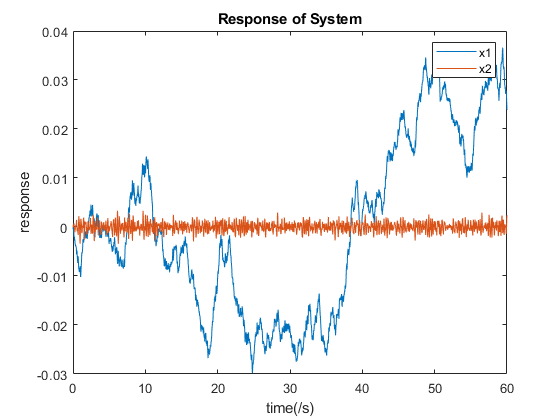

% Model Selection for simulation

%[out,uin,t] = rdid_lnr_mdl_ivp(fs,tval,C,refin);      % inverted pendulum
%[out,uin,t] = rdid_lnr_mdl_3dsys(fs,tval,C,refin);    % 3d system
%[out,uin,t] = rdid_lnr_mdl_3dsp(fs,tval,C,refin);     % special 3d system
%[out,uin,t] = rdid_nonlnr_mdl_4d(fs,tval,C,refin);     % nonlinear 4d system
[out,uin,t] = rdid_lnr_mdl_flexible_link(fs,tval,C,refin);

% % Exp. data
% load('theta_exp_8k_60s.mat')
% load('alpha_exp_8k_60s.mat')
% % time vector
%  t = theta(1,1:240000)';
% %sampling
%  fs = 8000;  % Sampling frequency
% %reference
%  dt = 1 / fs;         % step size
% 
% uin = theta(2,1:240000)';  % random input
% out = [theta(3,1:240000);alpha(2,1:240000)];
% plot(t,out(1,:),t,out(2,:))

% Args Config.

% number of dimensions not required
% it is optional in function getrd to limit the highest relative degree 
% n = [];

raw_data = out';
raw_input = uin;

% search settings for combination
srch_opts= {[-2 2],1/1000};  % {[start end],search step}
len_srch = size([srch_opts{1}(1):srch_opts{2}:srch_opts{1}(2)],2);

% data interval args
% mode = 'auto' or 'manul'
% for 'auto', a interval should be specified 
% arg list: {{mode,[interval(%)]}}
%crit_opts = {'manul',[]};
crit_opts = {'auto',[0.01 0.5]};

% optional windowing function. Default is Kasiver with beta 35
% win_opts = kaiser(size(t,1)/2+1,35);

win_opts =[];

% optional filter applying to raw output and input. Defalut empty.
% see MATLAB Signal Processing Toolbox
filt_opts =[];

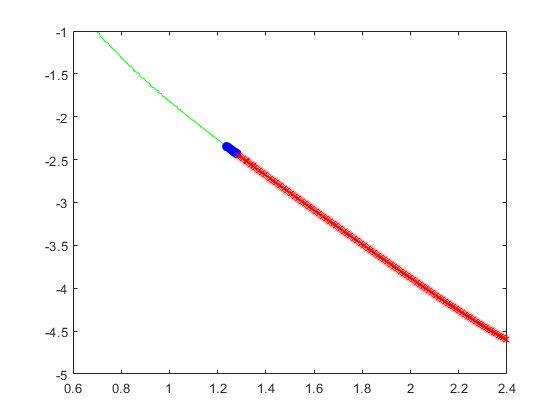

% core detection function - RelatTek
% returns ratios with relative degree of chosen output combinations
%========================================================================
tic
[rdval,combval,ptgval] = RelaTek([],t,raw_data,raw_input,srch_opts,crit_opts,win_opts,filt_opts);

toc

Elapsed time is 53.689254 seconds.


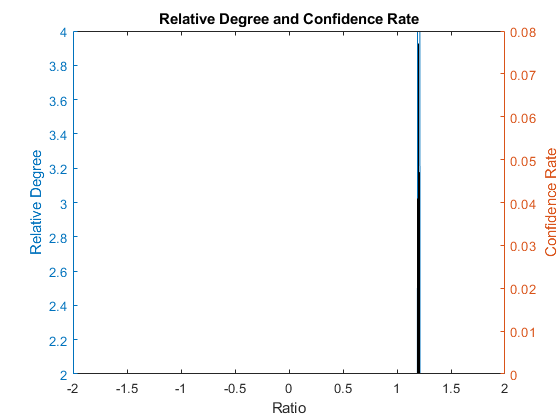

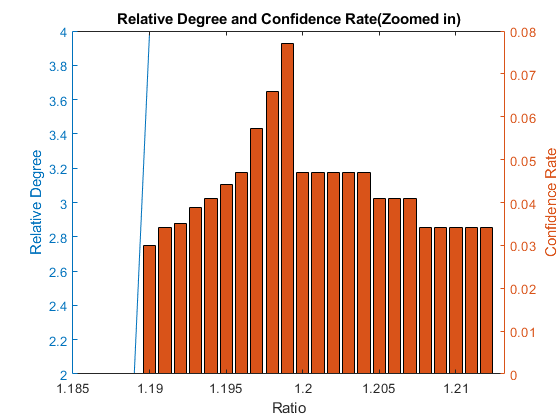

target_ratio = 1.1990

maxrd = 4

% Plots
%========================================================================
maxrd = max(rdval);             % max rd
minrd = min(rdval);             
num_of_max_rd = find(rdval==maxrd); % possible ratio for max rd
if size(combval,1) ~= 1         % manul mode
    if (maxrd~=minrd)&&(size(num_of_max_rd,1)>1) 
        
        % confidence rate
        ptgcfdt= ptgval(num_of_max_rd)./sum(ptgval(num_of_max_rd));
        num_of_max_ptgcfdt = find(ptgcfdt==max(ptgcfdt));        
        target_ratio = min(abs(combval(num_of_max_rd(1) + num_of_max_ptgcfdt - 1)));
        figure
        yyaxis left
        plot(combval,rdval)
        ylabel('Relative Degree')
        xlabel('Ratio')
        
        yyaxis right
        bar(combval(num_of_max_rd),ptgcfdt)
        ylabel('Confidence Rate')
        title('Relative Degree and Confidence Rate')
        
        figure
        yyaxis left
        plot(combval(num_of_max_rd(1)-2:num_of_max_rd(end)),rdval(num_of_max_rd(1)-2:num_of_max_rd(end)))
        
        ylabel('Relative Degree')
        xlabel('Ratio')
        yyaxis right
        bar(combval(num_of_max_rd),ptgcfdt)
        ylabel('Confidence Rate')
        title('Relative Degree and Confidence Rate(Zoomed in)')
       
        target_ratio
        maxrd
        
    else                                         % if only one max rd 
        figure
        plot(combval,rdval)
        ylabel('Relative Degree')
        xlabel('Ratio')
        title('Relative Degree')
        
        target_ratio = min(abs(combval(num_of_max_rd)))
        maxrd
        
    end
end